a_1=1.5

a_1 = 1.5000

up_x = 3

up_x = 3

up_t = 1

up_t = 1


x=up_x; %x范围
t=up_t; %t范围
down_x = 1

down_x = 1

down_t = 0

down_t = 0

tt = 0.01

tt = 0.0100

xx = 0.01

xx = 0.0100

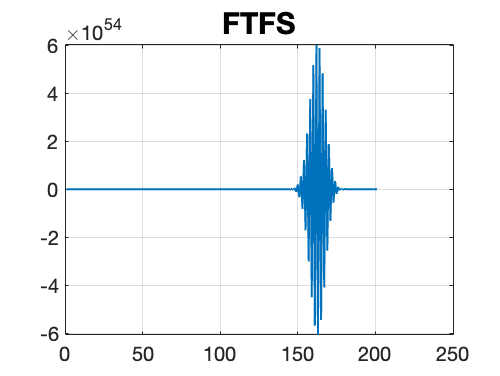


s=xx; %空间步长
e=tt; %时间步长
r=a*e/s; %柯朗数

xn=(x-down_x)/s; %x向点数
tm=(t-down_t)/e; %t向点数


u=zeros(xn+1,1);
X=zeros(xn+1,tm+1);

for j=1:tm+1
    if j==1
        for k=2:xn+1
            u(k)=sin((k-1)*s);
            u0=u;
        end
    else
        u0=u;
    X(:,j)=u;
    end
   
    for i=2:xn+1
        if i==xn+1
            u(i)=(1-r)*u0(i)+r*u0(i-1); %边界处换用FTBS格式
        else
            u(i)=(1+r)*u0(i)-r*u0(i+1);
        end
    end
    plot(u,'LineWidth',1)
    pause(0.1)
end
grid on
title('FTFS','FontSize',15,'FontWeight','bold');